% check the dataset is present:
clear;

if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames');
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

net = googlenet;

inputSize = net.Layers(1).InputSize;

im = testing.readimage(1);%first 

im = imresize(im,inputSize(1:2)); %resize image from 227*227 to 224*224

label = classify(net,im);

total = size(im,1) * size(im,2)

total = 50176

numel(im(:,:,1))

ans = 50176

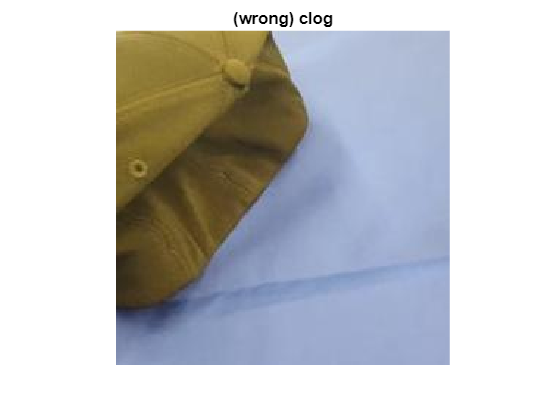


wrong1 = find(label~=testing.Labels(1));

if (~isempty(wrong1))
    testing.Labels(wrong1);
    wrongIm= testing.readimage(wrong1);
    figure;
    imshow(wrongIm)
    title("(wrong) "+string(label))
end

testing.reset
training.reset

net2 = resnet50();

inputSize = net2.Layers(1).InputSize;
augTrain = augmentedImageDatastore(inputSize(1:2), training, 'ColorPreprocessing', 'gray2rgb');
augTest = augmentedImageDatastore(inputSize(1:2), testing, 'ColorPreprocessing', 'gray2rgb');
%storing the imgaes as RGB


% fc1000 is the the only fully connected layer avaliabble in resnet50
layer = 'fc1000';

layer = 'fc1000'


featuresTrain = activations(net2,augTrain,layer,'OutputAs','rows');
featuresTest = activations(net2,augTest,layer,'OutputAs','rows');

% Solution:
train_labels = training.Labels;
test_labels = testing.Labels;

kNN = fitcknn(featuresTrain, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, featuresTest);

[c, order] = confusionmat(test_labels, predictions);
   
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 96.6667


pred_test2_labels = classify(net2,augTest);


% Find incorrect images:

% check the dataset is present:
clear;

if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames');
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

net3 = googlenet;

inputSize = net3.Layers(1).InputSize;
lgraph = layerGraph(net3);

lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});

numClasses = numel(categories(training.Labels));

newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);

lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');


pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),training, ...
    'DataAugmentation',imageAugmenter);

augimdsTest = augmentedImageDatastore(inputSize(1:2),testing);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',augimdsTest, ...
    'ValidationFrequency',3, ...
    'ValidationPatience',Inf, ...
    'Verbose',false ,...
    'Plots','training-progress');

net3 = trainNetwork(augimdsTrain,lgraph,options);

[PredLabel,PredData] = classify(net3,augimdsTest);

accuracy = mean(PredLabel == testing.Labels)*100

accuracy = 100

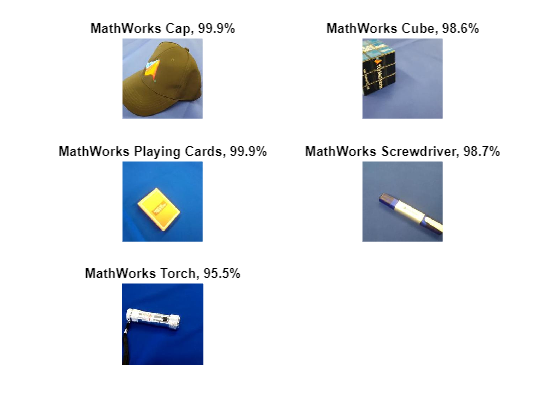


uni = unique(PredLabel);

idx = [];
for i=1:1:size(uni,1)

    idx(:,end+1) = max(find(PredLabel==uni(i)));

end

figure
for i = 1:5
    subplot(3,2,i)
    I = readimage(testing,idx(i));
    imshow(I)
    label = PredLabel(idx(i));
    title(string(label) + ", " + num2str(100*max(PredData(idx(i),:)),3) + "%");
end

%https://uk.mathworks.com/help/deeplearning/gs/classify-image-using-pretrained-network.html 
%https://uk.mathworks.com/help/vision/ug/image-category-classification-using-deep-learning.html 
%https://uk.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html 
%https://www.google.com/search?q=resnet50()&rlz=1C1CHBF_en-GBGB964GB964&oq=resnet50()&aqs=chrome..69i57j0i30l9.825j0j7&sourceid=chrome&ie=UTF-8